# **Riemann Integrabirity of One-Variable Functions**

## **1. Definition of Riemann Integrabirity**

Let $f:[a,b] \rightarrow [m,M]$ be a real-valued bounded function on an interval $[a,b]$, that is, 

the graph of $f$ is contained in a closed rectangle $[a,b]\times[m,M]$. 

We define a Riemann sum of . We introduce division of 

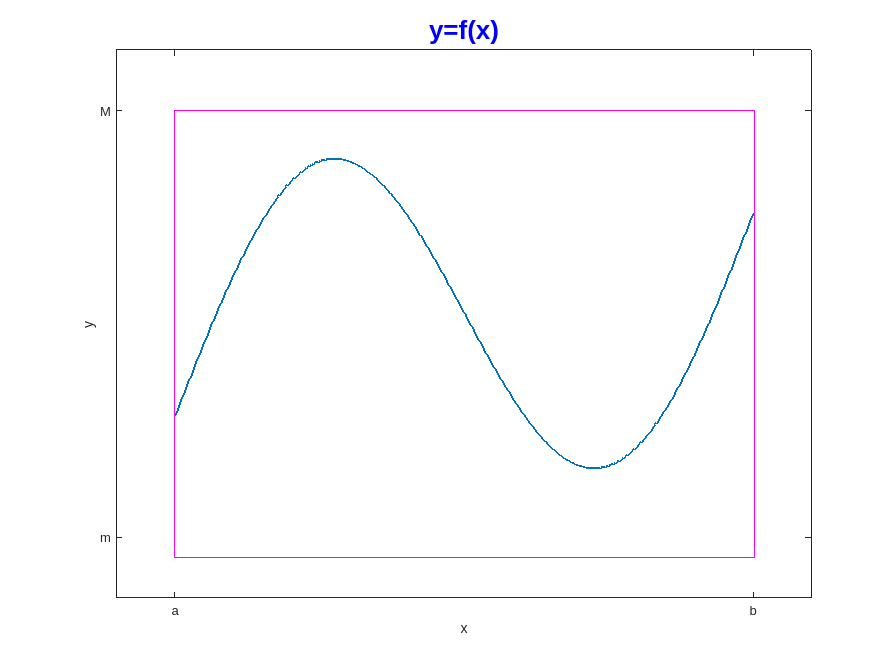

x = 0:0.002:1;
f=sin(2*pi*x)+x+1.2*ones(1,501);
z=1.8*ones(1,501);
w=zeros(1,501);
for k=1:501
	w(1,k)=min(f(1,k),z(1,k));
end

plot(f,'LineWidth',2);
ylim([0.3 3])
xlim([-50 551])
title('y=f(x)','Color','blue','FontSize',20)
xticks([1 501])
xticklabels({'a','b'})
xlabel('x')
yticks([0.6 2.7])
yticklabels({'m','M'})
ylabel('y')
hold on
rectangle('Position',[1 0.5 501 2.2],'EdgeColor','magenta')
hold off

We define a Riemann sum of $f$. We introduce division of $[a,b]$


$$\Delta: a=a_0<a_1<\cdots<a_n=b, 
\quad
|\Delta|:=
\max_{i=1,\ldots,n}(a_i-a_{i-1}).$$


Pick up arbitrary$\xi_1\in[a_{i-1},a_i]$  for $i=1,\ldots,n$. Set 


$$R(\Delta)
:=
\sum_{i=1}^n
f(\xi_i)(a_i-a_{i-1}). $$


This is a Riemann sum of $f$. This depends not only on the division $\Delta$ but also the choice of $\xi_1,\ldots,\xi_n$. Note that 


$$m(b-a)
\leq
R(\Delta)
\leq
M(b-a).$$


We say that $f$ is Riemann integrable if there exists a cosntant $\alpha$ such that 


$$R(\Delta) \rightarrow \alpha 
\quad
(|\Delta| \rightarrow 0),$$


which is independent of the choices of $\Delta$ and $\xi_1,\ldots,\xi_n$. 

In this case the real number $\alpha$ is said to be the Riemann integral of $f$ on the interval $[a,b]$ and is denoted by  


$$\int_a^bf(x)dx.$$


It is wellknown that if $f \in C[a,b]$, then $f$ is uniformly continuous on $[a,b]$ and Riemann integrable on $[a,b]$. 

More generally if there exist finite numbers $b_0, b_1, \ldots, b_N \in [a,b]$ such that 

$a=b_0<b_1<\cdots<b_N=b$, $f \in C(b_{j-1},b_j)$, $j=1,\ldots,N$

and limits of finite values 


$$f(b_0+0),
\quad
f(b_1-0), 
\quad
f(b_1+0),
\quad
\ldots,
\quad
f(b_N-0)$$


exit, that is, $f$ is piecewise continuous on $[a,b]$, then $f$ is Riemann integrable on $[a,b]$ .

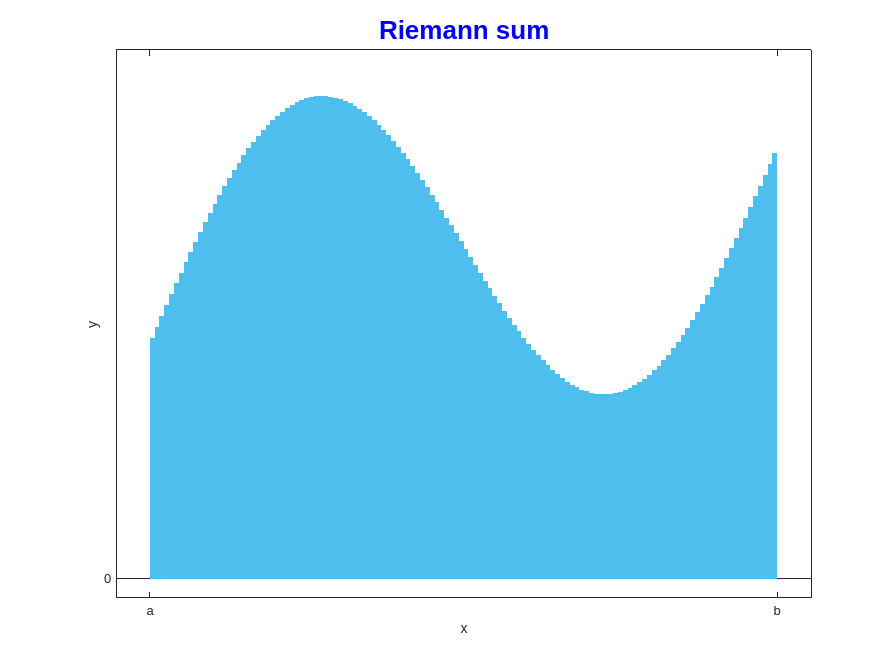

n =130;
g=zeros(1,n);
for j=1:n
    g(1,j)=sin(2*pi*(2*j-1)/2/n)+(2*j-1)/2/n+1.2;
end

b=bar(g);
b.FaceColor = '#4DBEEE';
b.EdgeColor = '#4DBEEE';
title('Riemann sum','Color','blue','FontSize',20)
ylim([-0.1 2.7])
xlim([-n/20 n+1+n/20])
xticks([1/2 n+1/2])
xticklabels({'a','b'})
xlabel('x')
yticks([0])
yticklabels({'0'})
ylabel('y')

If $f$ is continuous and nonnegative, then the Riemann integral $\displaystyle\int_a^bf(x)dx$  is the area unclosed by $y=0$, $x=a$, $x=b$, and $y=f(x)$. 

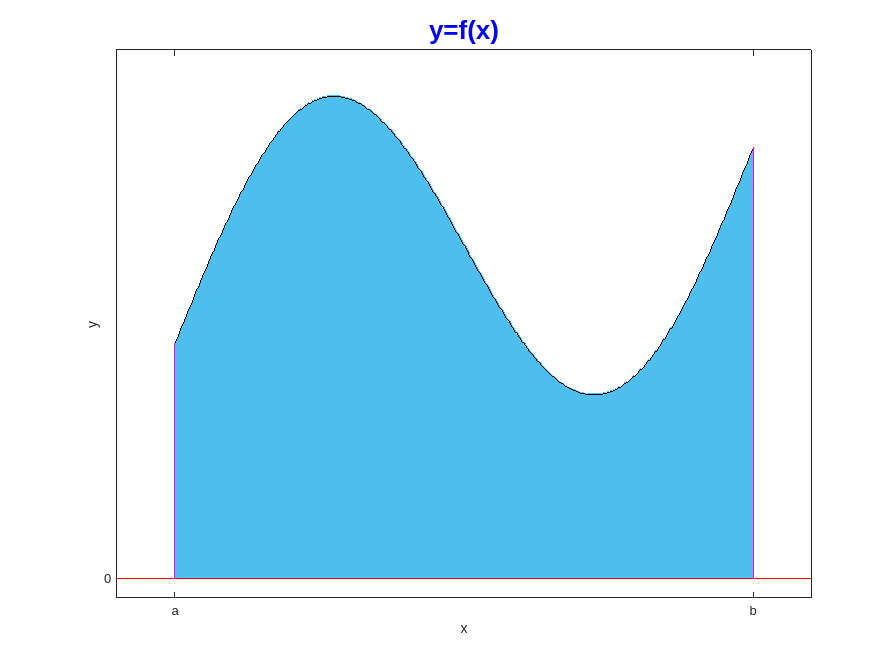

plot(f,'LineWidth',2);
ylim([-0.1 2.7])
xlim([-50 551])
title('y=f(x)','Color','blue','FontSize',20)
xticks([1 501])
xticklabels({'a','b'})
xlabel('x')
yticks([0])
yticklabels({'0'})
ylabel('y')
hold on
area(f)
colororder('#4DBEEE')
rectangle('Position',[-50 0 601 0],'EdgeColor','red')
rectangle('Position',[1 0 0 f(1,1)],'EdgeColor','magenta')
rectangle('Position',[501 0 0 f(1,501)],'EdgeColor','magenta')
hold off

Let $c \in (a,b)$. Suppose that $f$ is nonnegative and continuous for $x \ne c$,  and has a jump discontinuity at $x=c$. 

The Riemann integral $\displaystyle\int_a^bf(x)dx$ is the area unclosed by $y=0$, $x=a$, $x=b$, $y=f(x)$, 

and the line segment between two points $\bigl(c,f(c-0)\bigr)$ and $\bigl(c,f(c+0)\bigr)$. 

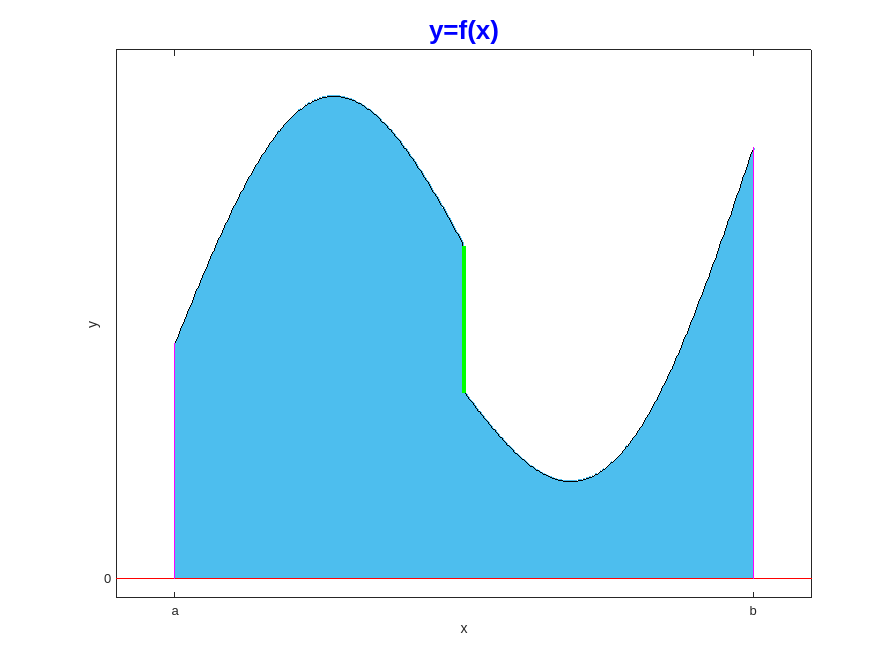

x = 0:0.002:1;
h=sin(2*pi*x)+x+1.2*ones(1,501);
for k=251:501
	h(1,k)=f(1,k)-1.5*(1-x(1,k));
end

plot(h,'LineWidth',2);
ylim([-0.1 2.7])
xlim([-50 551])
title('y=f(x)','Color','blue','FontSize',20)
xticks([1 501])
xticklabels({'a','b'})
xlabel('x')
yticks([0])
yticklabels({'0'})
ylabel('y')
hold on
area(h)
colororder('#4DBEEE')
rectangle('Position',[-50 0 601 0],'EdgeColor','red')
rectangle('Position',[1 0 0 f(1,1)],'EdgeColor','magenta')
rectangle('Position',[501 0 0 f(1,501)],'EdgeColor','magenta')
rectangle('Position',[251 h(1,251) 0 f(1,251)-h(1,251)],'EdgeColor','green','LineWidth',3)
hold off

If $f$ is continuous and takes both positive and negative values, then 


$$\displaystyle\int_a^bf(x)dx
= 
\text{the area of positive part}
-
\text{the area of negative part}.$$


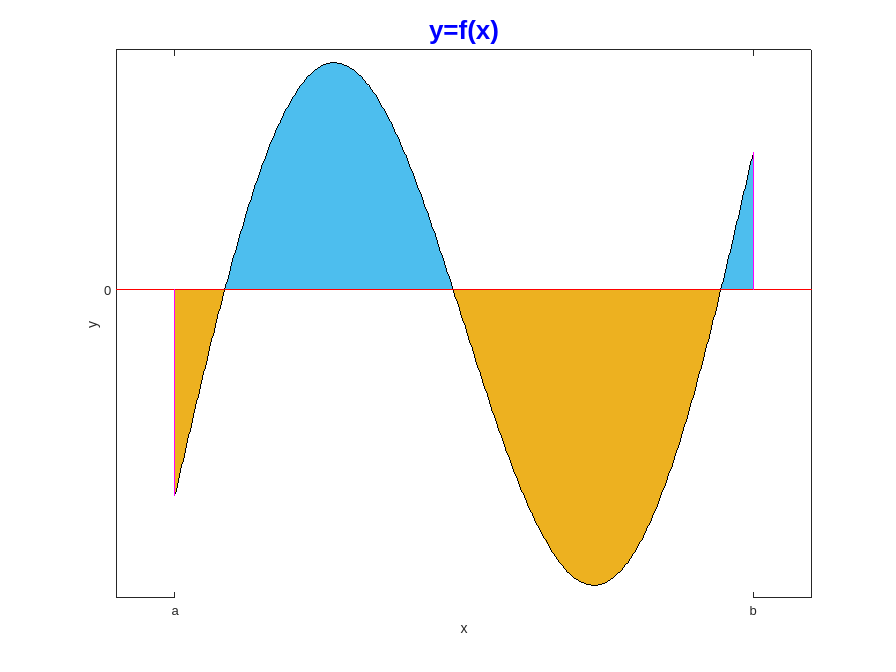

plot(f,'LineWidth',2);
ylim([0.9 2.5])
xlim([-50 551])
title('y=f(x)','Color','blue','FontSize',20)
xticks([1 501])
xticklabels({'a','b'})
xlabel('x')
yticks([1.8])
yticklabels({'0'})
ylabel('y')
hold on
area(f);
area(z)
area(w)
newcolors = [1 1 1; 0.3010 0.7450 0.9330; 0.9290 0.6940 0.1250];
colororder(newcolors)
rectangle('Position',[-50 1.8 601 0],'EdgeColor','red')
rectangle('Position',[1 f(1,1) 0 1.8-f(1,1)],'EdgeColor','magenta')
rectangle('Position',[501 1.8 0 f(1,501)-1.8],'EdgeColor','magenta')
hold off